# Comparison of Nonlinear and Linear Models using Dynamic Simulation

**Sachin C. Patwardhan*, Anjali P. Deshpande and Sharad Bhartiya* **

(*) Dept. of Chemical Engineering,

 Indian Institute of Technology Bombay, Mumbai 400076 India  

## Introduction

Having obtained a local [linear discrete time model](matlab:open('./L04_DiscreteModels.mlx')) from a set of nonlinear ODE, we now see how these models can be used to simulate the process online. In fact, since we intend to use them in place of the original mechanistic nonlinear dynamic model, it is important to validate the discrete linear model by simulating linear and nonlinear models under identical input conditions and get a feel for the approximation errors. 

**Learning Objective: **

- To check the accuracy of the linear perturbation model by comparing the model predictions with the simulated state dynamics obtained using the nonlinear mechanistic model. 

## Simulation of Plant Dynamics

### Nonlinear Plant Simulation 

To simulate the nonlinear system dynamics, we integrate ODE-IVP over interval $ t\in [kT,(k+1)T]$ for $k=0,1,2,\ldotp \ldotp \ldotp \ldotp ,N$

$\begin{array}{l}
\frac{\textrm{dX}}{\textrm{dt}}=f\left(X\left(t\right),U\left(t\right),D\left(t\right)\right)\\
\textrm{initial}\;\textrm{condition}:X\left(k\;T\right)\equiv X\left(k\right)
\end{array}$    ------(1)

under the following assumptions 

- Manipulated inputs are piecewise constant 

$U(t)=U(k)    $ for  $ t\in [kT,(k+1)T]$   for $k=0,1,2,\ldotp \ldotp \ldotp \ldotp ,N$ ------(2)

-  Sampling interval is sufficiently small and disturbance variations can be adequately represented as piece-wise constant signals 

$D(t)=D(k)    $ for   $ t\in [kT,(k+1)T]$  for $k=0,1,2,\ldotp \ldotp \ldotp \ldotp ,N$  ------(3)

Let us assume that we are given initial condition $X\left(0\right)=X_s +x\left(0\right)$ and some arbitrary input sequences in the neighborhood of equilibrium inputs$\left(U_s ,D_s \right)$

$\left\lbrace U\left(k\right)\right\rbrace =\left\lbrace U\left(0\right),U\left(1\right),U\left(2\right),\ldotp \ldotp \ldotp \ldotp \ldotp ,U\left(N\right)\right\rbrace =\left\lbrace u\left(0\right)+U_s ,u\left(1\right)+U_s ,u\left(2\right)+U_s \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp ,u\left(N\right)+U_s \ldotp \right\rbrace$  ------(4)

$\left\lbrace D\left(k\right)\right\rbrace =\left\lbrace D\left(0\right),D\left(1\right),D\left(2\right)\ldotp \ldotp \ldotp \ldotp \ldotp ,D\left(N\right)\right\rbrace =\left\lbrace d\left(0\right)+D_s ,d\left(1\right)+D_s ,d\left(2\right)+D_s ,\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp ,d\left(N\right)+D_s \ldotp \right\rbrace$  ------(5)

and we are interested in generating the state sequence $\left\lbrace X\left(k\right):1,2,\ldotp \ldotp \ldotp \ldotp ,N\right\rbrace$ when the system is subjected to these input sequences.  The state dynamics at ${\left(k+1\right)}^{\textrm{th}}$ instant can be  obtained by integrating the nonlinear function for one sampling interval as follows

$X\left(k+1\right)=X\left(k\right)+\int_{k\;T}^{\left(k+1\right)\;T} \mathit{\mathbf{f}}\left(X\left(\tau \right),U\left(k\right),D\left(k\right)\right)d\tau$   --------(6)

Defining a discrete time operator, 

$F\left\lbrack X\left(k\right),U\left(k\right),D\left(k\right)\right\rbrack \equiv X\left(k\right)+\int_{k\;T}^{\left(k+1\right)\;T} \mathit{\mathbf{f}}\left(X\left(\tau \right),U\left(k\right),D\left(k\right)\right)d\tau$   -------(7)

Thus the discrete time nonlinear dynamic model can be represented as 

$X\left(k+1\right)=F\left\lbrack X\left(k\right),U\left(k\right),D\left(k\right)\right\rbrack$  ---------(8)

The integral on the RHS of equation (7), in general, cannot be computed analytically. However, we can solve the nonlinear discrete state transition equation using various numerical techniques.

**Method 1: **The simplest method is** Explicit Euler Integration**

$X\left(k+1\right)=X\left(k\right)+T\;\mathit{\mathbf{f}}\left(X\left(k\right),U\left(k\right),D\left(k\right)\right)$  -----(9a)

This implies that 

$F\left\lbrack X\left(k\right),U\left(k\right),D\left(k\right)\right\rbrack \equiv X\left(k\right)+T\;\mathit{\mathbf{f}}\left(X\left(k\right),U\left(k\right),D\left(k\right)\right)$   ------(9b)  

This method works only when the sampling interval T is sufficiently small. If it is desired to use this approach, then it is important to check using extensive simulation studies that the chosen sampling interval generates reasonably accurate state profiles. 

**Method 2: **A more robust variant is Crank-Nicholson method 

$X\left(k+1\right)=X\left(k\right)+\frac{T}{2}\left\lbrace \;\mathit{\mathbf{f}}\left(X\left(k\right),U\left(k\right),D\left(k\right)\right)+f\left(X\left(k+1\right),U\left(k\right),D\left(k\right)\right)\right\rbrace$  ----(10) 

This is an implicit solver and equation can be rearranged as 

$X\left(k+1\right)=\bar{X} \left(k+1\right)+\frac{T}{2}\left\lbrace \;f\left(X\left(k+1\right),U\left(k\right),D\left(k\right)\right)\right\rbrace$ ------(11a)

$\bar{X} \left(k+1\right)=X\left(k\right)+\frac{T}{2}\;\mathit{\mathbf{f}}\left(X\left(k\right),U\left(k\right),D\left(k\right)\right)$ ----(11b)

At instant k, $\bar{X} \left(k+1\right)$ can be computed using the prior information. However, equation (11a) is an implicit function of $X\left(k+1\right)$ and needs to be solved using some iterative scheme such as Newton-Raphson method. This method is computationally intensive but robust and less prone to instabilities due to approximation errors. 

**Method 3:** Runge Kutta method, e.g. Second Order RK method

$\begin{array}{l}
\tilde{X} \left(k+1\right)=X\left(k\right)+T\;\mathit{\mathbf{f}}\left(X\left(k+1\right),U\left(k\right),D\left(k\right)\right)\\
X\left(k+1\right)=X\left(k\right)+\frac{T}{2}\left\lbrace \mathit{\mathbf{f}}\left(X\left(k\right),U\left(k\right),D\left(k\right)\right)+\mathit{\mathbf{f}}\left(\tilde{X} \left(k+1\right),U\left(k\right),D\left(k\right)\right)\right\rbrace \;
\end{array}$----(12)

Essentially any ODE IVP solver can be used to approximate $F\left\lbrack X\left(k\right),U\left(k\right),D\left(k\right)\right\rbrack$. In this course we use MATLAB's variable step size Runge-Kutta solver `ode45. ` 

    After selecting the ODE solver, given $X\left(0\right)=x\left(0\right)+X_s$ and manipulated input sequence $\left\lbrace U\left(k\right)\right\rbrace =\left\lbrace U\left(0\right),U\left(1\right),U\left(2\right)\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \right\rbrace$and arbitrary disturbance input sequence, the state sequence can be generated sequentially as follows 


$$X\left(1\right)=F\left\lbrack X\left(0\right),U\left(0\right),D\left(0\right)\right\rbrack$$



$$\Downarrow$$



$$X\left(2\right)=F\left\lbrack X\left(1\right),U\left(1\right),D\left(1\right)\right\rbrack$$



$$\begin{array}{l}
\Downarrow \\
\vdots 
\end{array}$$


$X\left(k+1\right)=F\left\lbrack X\left(k\right),U\left(k\right),D\left(k\right)\right\rbrack$ ------(13)


$$\vdots$$


and so on. 

### Simulation Using Linear Discrete Time Model

The discrete linear perturbation model developed in the previous lesson is represented as follows 

$x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)+\Gamma_d d\left(k\right)$---------(14)

  Now, given $x\left(0\right)$, the initial state and arbitrary manipulated input sequence, $\left\lbrace u\left(k\right)\right\rbrace =\left\lbrace u\left(0\right),u\left(1\right),u\left(2\right)\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \right\rbrace$ and arbitrary disturbance input sequence $\left\lbrace d\left(k\right)\right\rbrace =\left\lbrace d\left(0\right),d\left(1\right),d\left(2\right)\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \right\rbrace$, as in equations (4) and (5),  the linear discrete time model (14) can be used for simulating the system dynamics as follows; 


$$x\left(1\right)=\Phi x\left(0\right)+\Gamma u\left(0\right)+\Gamma_d d\left(0\right)$$



$$\Downarrow$$



$$x\left(2\right)=\Phi x\left(1\right)+\Gamma u\left(1\right)+\Gamma_d d\left(1\right)$$



$$\Downarrow$$


........


$$x\left(k+1\right)=\Phi x\left(k\right)+\Gamma u\left(k\right)+\Gamma_d d\left(k\right)$$



$$\Downarrow$$


......

and so on to get the perturbation state sequence $\left\lbrace x\left(k\right)\right\rbrace =\left\lbrace x\left(1\right),x\left(2\right),x\left(3\right)\ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \ldotp \right\rbrace$. 

## Dynamic Simulation of Quadruple Tank Process

Let us take an example of Quadruple Tank system (Johansson, 2000) to evaluate the efficacy of the linear discrete time model obtained from nonlinear ODE. If the models match within a *small *range of the operating point, they will exhibit similar behavior for same inputs. We assume that the process is operating at a given steady state with constant steady state inputs applied at time 0, i.e. $X\left(0\right)=X_s \;\;\textrm{and}\;x\left(0\right)=X\left(0\right)-X_s =\bar{0}$  while carrying out simulations. 

### Case 1: Smaller Perturbations around the Steady State Inputs

We introduce perturbations in the applied inputs, let the magnitude of perturbations be small as shown below. 

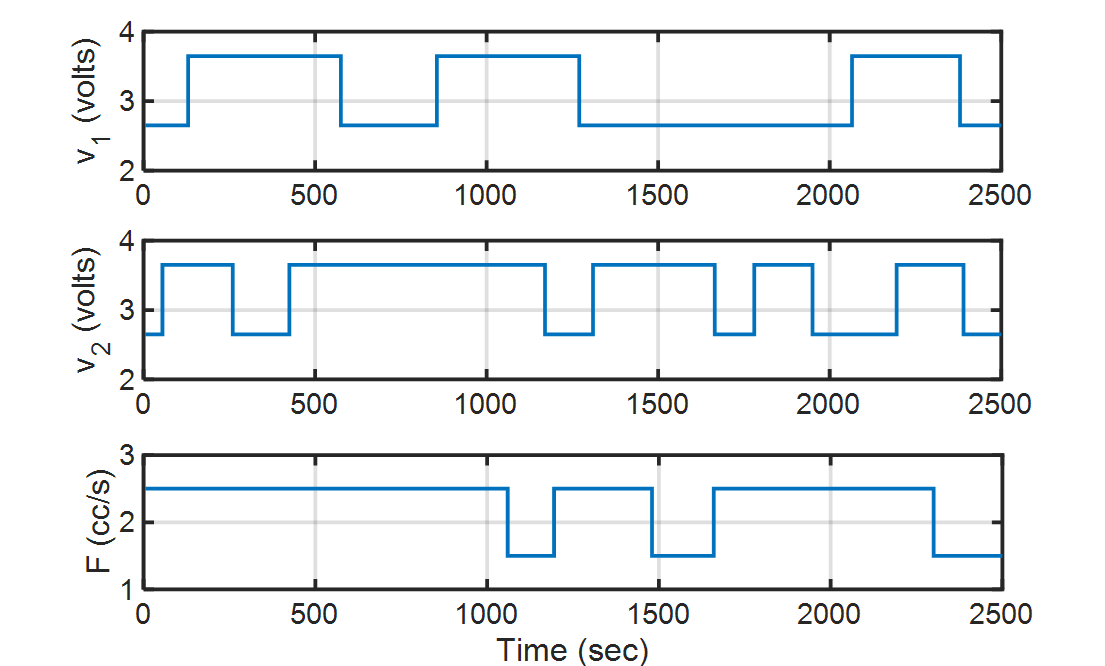

**Figure 1: Smaller Perturbation Inputs**

The variations in the states are as shown in the following figure. 

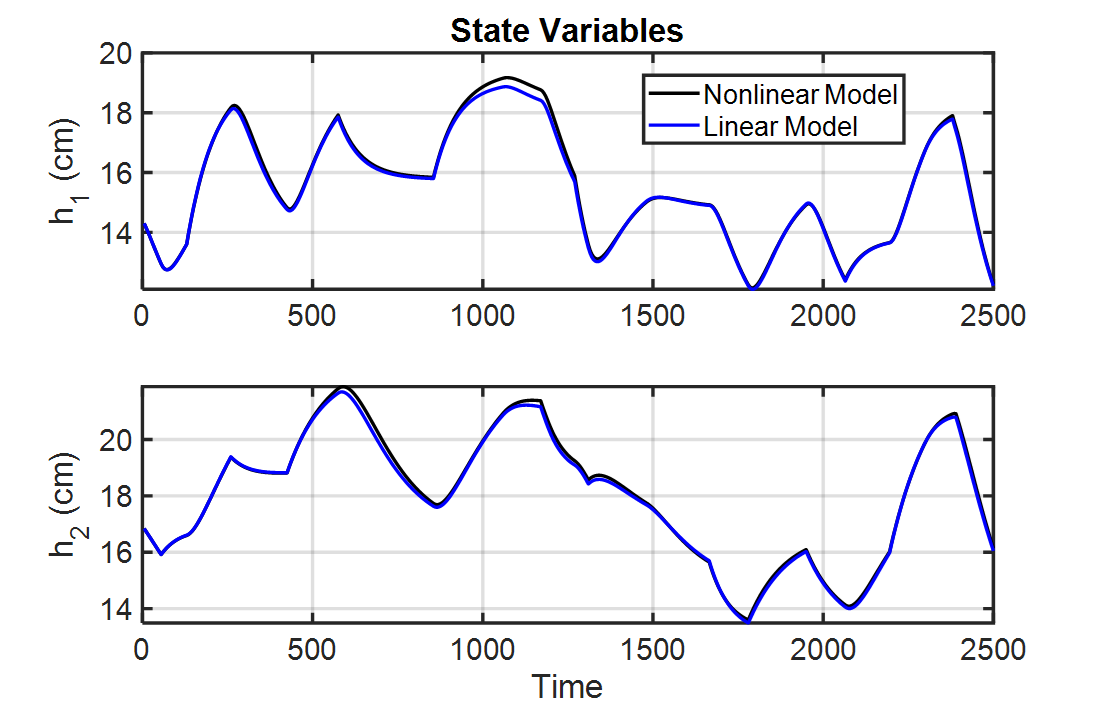

**Figure 2 a: States for Linear and Nonlinear Simulation**

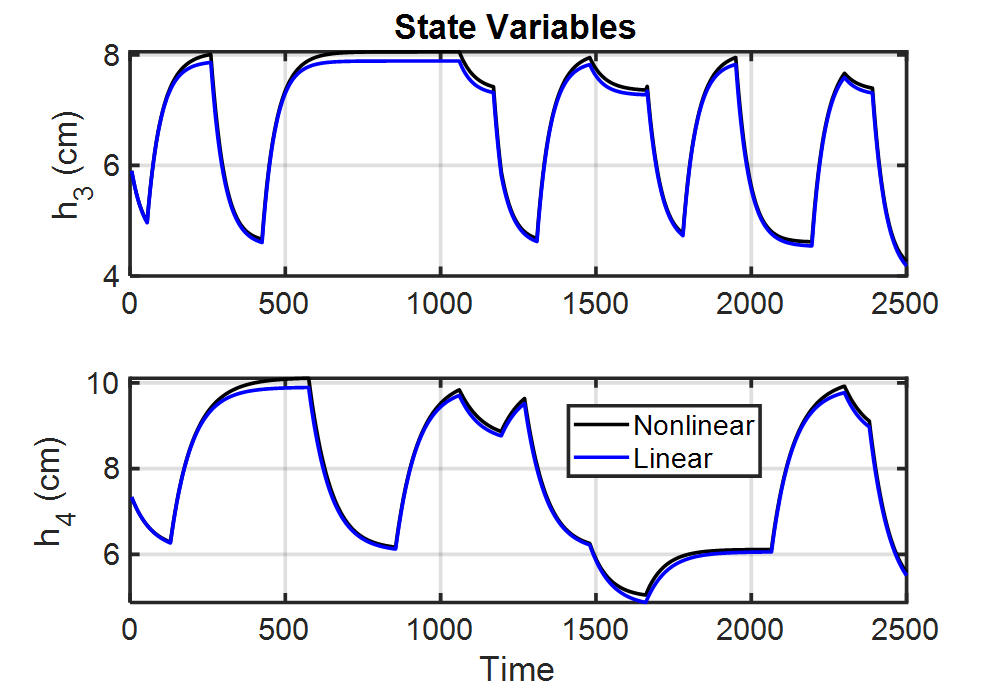

**Figure 2 b: States for Linear and Nonlinear Simulation**

We can observe that the linear model performs quite well and the states are almost same as the nonlinear model over a quite large operating region, when the input perturbations are small. 

### Case 2: Larger Perturbations around the Steady State Inputs

We now increase the amplitude of perturbations and again compare the state dynamics with both the models. When 20% perturbations are given in the inputs simultaneously, some differences start occurring.

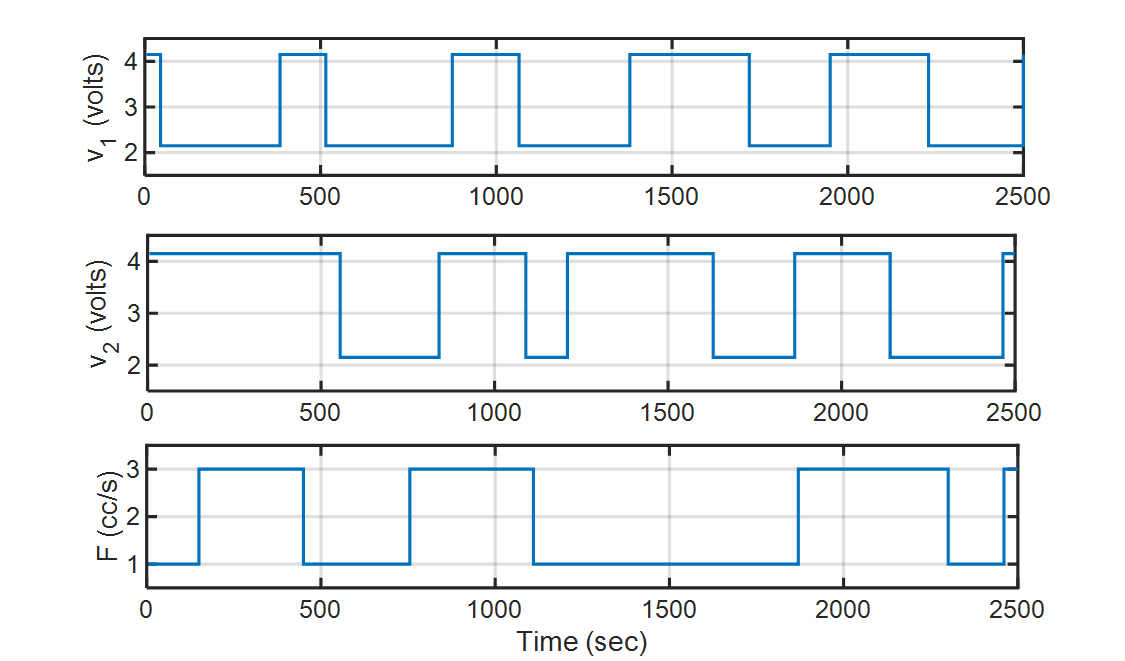

**Figure 3: Larger Perturbation Inputs**

The variations in the states are as shown in the following two figures. 

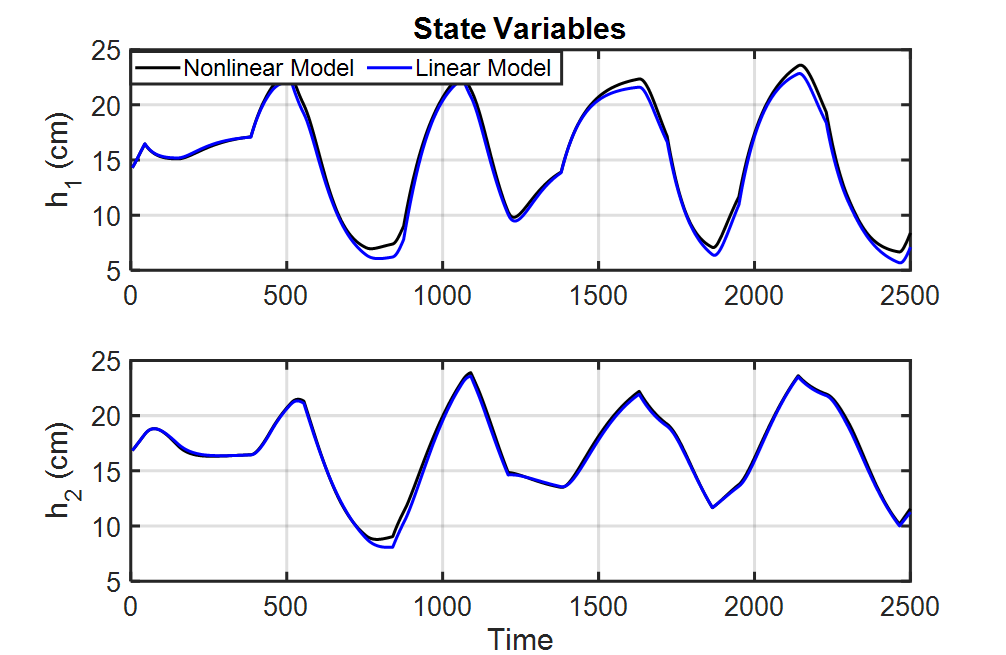

**Figure 4 a: States for Linear and Nonlinear Simulation**

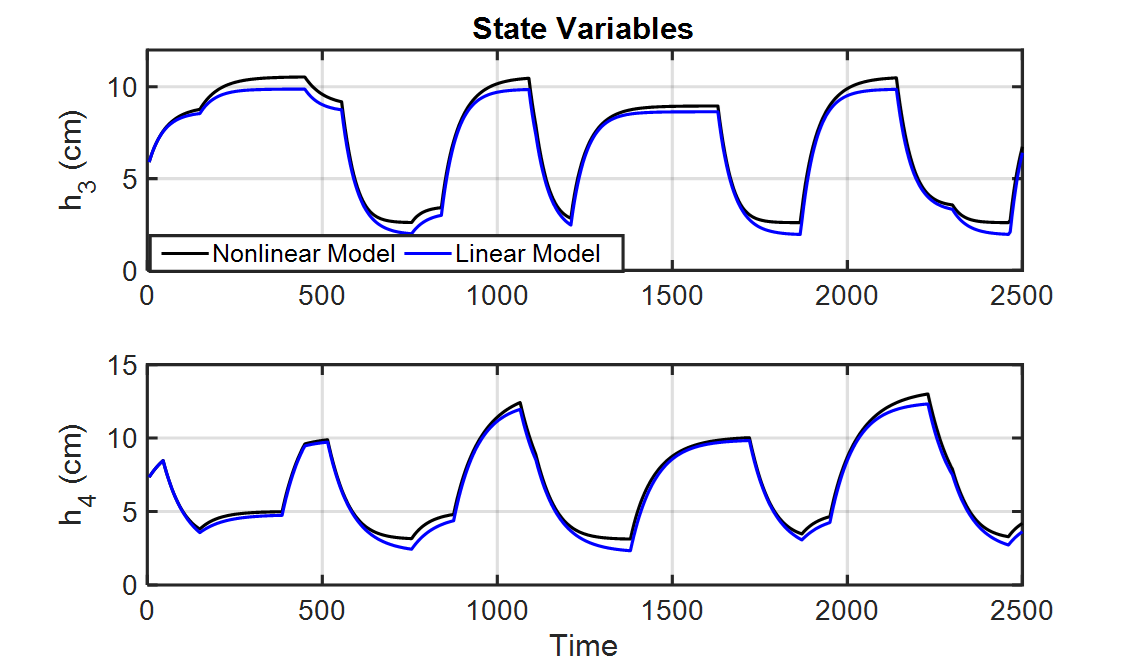

**Figure 4 b: States for Linear and Nonlinear Simulation**

From the above study and the outputs, we can conclude that

- When input variations are relatively small, dynamic behavior of discrete time linear model matches the nonlinear system dynamic behavior reasonably well. 

- Larger mismatch develops between linear and nonlinear model based simulations for larger magnitude input perturbations. However, the linear model is able to capture qualitative behavior of state dynamics reasonably well even for large magnitude perturbations. 

However this study gives us a confidence that the linear models can be used in place of nonlinear models for predictive controller synthesis. Let us now perform simulations on Q Tank process. 

## Comparative Evaluation of Nonlinear and Linear Model Predictions using Quadruple Tank Simulation

We will now compare the behaviors of the nonlinear discrete model and the linear discrete model under different operating conditions and under variations in the applied inputs. We compare the state variability obtained using linear and nonlinear model as follows 

${\textrm{Nonlinear}\;\textrm{Model}:\;S}_i^2 =\sum_{k=0}^N {\left(X_i \left(k\right)-X_{s,i} \left(k\right)\right)}^2 \;\;\textrm{and}\;\;\textrm{Linear}\;\textrm{Model}:\;\;s_i^2 =\sum_{k=0}^N {\left(x_i \left(k\right)\right)}^2$  ------(15)

In addition, we also compute approximation error indices as follows 

$E_i^2 =100\times \frac{\sum_{k=0}^N {\left(X_i \left(k\right)-X_{s,i} \left(k\right)-x_i \left(k\right)\right)}^2 }{\sum_{k=0}^N {\left(X_i \left(k\right)-X_{s,i} \left(k\right)\right)}^2 }\;$      ------(16) 

These indices can be used to assess the quality of approximation using the discrete linear model.  

close all    % close all open figures 
clear all     % clear work space 
clc             % clear screen 
format short
global QTank U_k D_k
fprintf('\n  Quadruple Tank System: Open Loop Simulation \n') ;


  Quadruple Tank System: Open Loop Simulation 


**Task 1:**  Specify operating Condition as** Minimum Phase  or Non-minimum Phase. **This will load the previously saved Q tank parameters corresponding to the chosen operating point.

operating_pt=1;
if ( operating_pt == 1 )                        % Minimum phase system
    load QTank_MinPhase_Model.mat
elseif ( operating_pt == 2 )                    % Non-Minimum phase system 
    load QTank_NonMinPhase_Model
end

N_samples = 500 ;          % No. of samples in simulation run
samp_T = QTank.samp_T  ;   % Sampling interval 

n_st = length( QTank.Xs ) ;   % No. of states 
n_op =  length( QTank.Ys ) ;  % No. of measured o/p 
n_ip = length( QTank.Us ) ;   % No. of man. inputs  
n_ud = length( QTank.Ds ) ;   % Unmeasured disturbance

% Create matrices for storing original variables 
Xk = zeros(n_st, N_samples) ;      % Matrix to store state sequence          
Uk = zeros(n_ip, N_samples) ;      % Matrix to store manipulated input sequence 
Dk = zeros(n_ud, N_samples) ;      % Matrix to store unmeasured disturbance sequence
Yk = zeros(n_op, N_samples) ;      % Matrix to store measured output sequence

% Create Matrices for storing perturbation variables
xk = zeros(n_st, N_samples) ;       % Matrix to store perturbation state sequence          
uk = zeros(n_ip, N_samples) ;       % Matrix to store perturbation manipulated input sequence 
dk = zeros(n_ud, N_samples) ;       % Matrix to store perturbation unmeasured disturbance sequence
yk = zeros(n_op, N_samples) ;       % Matrix to store perturbation measured output sequence

Xk_lin = zeros(n_st, N_samples) ;   % Matrix to store state sequence computed using linear model 
Yk_lin = zeros(n_op, N_samples) ;   % Matrix to store measured output sequence computed using linear model

The process initially starts at the selected steady state operating point. 

% Process Initial conditions
Xk(:,1) = QTank.Xs ;
Yk(:,1) = QTank.C_mat * Xk(:,1) ;     

% Perturbation Model: Initial conditions
xk(:,1) = Xk(:,1) - QTank.Xs  ;   
yk(:,1) = Yk(:,1) - QTank.Ys   ;
Xk_lin(:,1) = xk(:,1) + QTank.Xs ;
Yk_lin(:,1) = yk(:,1) + QTank.Ys   ;

 % Specify input perturbations 


**Task 2:** Input Type - Enter (1) for **Step Change** (2) for **Random Binary Input **

We can give different types of inputs such as step or random binary to excite the process

input_type=3  ;

**Task 3:** If you select input_type as 1 for introducing step change, then specify which input should undergo a step change?  Users can select Flow 1, flow 2 or Disturbance flow

if (input_type == 1)
    input_no=   2;

**Task 4:** Also select how much step change is to be given..  

    step_magnitute= 0.5;
    ip1 = zeros( N_samples,1) ;
    ip2 = zeros( N_samples,1) ;
    ip3 = zeros( N_samples,1) ;
    if( input_no == 1 )
        ip1(51:end) = step_magnitute ;
    elseif( input_no == 2 )
        ip2(51:end) = step_magnitute ;
    else
        ip3(51:end) = step_magnitute ;
    end
elseif (input_type == 2)
    % Random Binary Signal (RBS) inputs


**Task 5:** If you select input_type as 2 or 3, specify signal Amplitude. The inputs are generated using [idinput ](https://in.mathworks.com/help/ident/ref/idinput.html?requestedDomain=)command in MATLAB System Identification Toolbox 

    RBS_amplitude= 0.5;
    ip1 = RBS_amplitude * idinput(N_samples, 'rbs', [0.0 0.025] ) ;
    ip2 = RBS_amplitude * idinput( N_samples,'rbs', [0 0.025] ) ;
    ip3 = RBS_amplitude * idinput( N_samples,'rbs', [0 0.025] ) ;
else
    RGS_amplitude= 0.6;
    ip1 = RGS_amplitude * idinput(N_samples, 'rgs', [0.0 0.025] ) ;
    ip2 = RGS_amplitude * idinput( N_samples,'rgs', [0 0.025] ) ;
    ip3 = RGS_amplitude * idinput( N_samples,'rgs', [0 0.025] ) ;
end
uk = [ ip1' ; ip2' ]  ;             % Specify perturbation input sequence
dk = ip3' ;                          % Measured disturbance

**Plant dynamic simulation in open loop **

Process simulation from $k\;\textrm{to}\;k+1$is done using linear discrete time model as well as nonlinear ODE model. In the nonlinear simulation, we can select the solver for solving the differential equations which are defined in the function **QTank_Dynamics**.m

**Task 6: **Choice of ODE Solver (1) for **Explicit Euler** OR (2) for **Runge Kutta **for solving the nonlinear ODEs online.

If we select Runge Kutta, a variable step size Runge Kutta solver [MATLAB ODE 45](https://in.mathworks.com/help/matlab/ref/ode45.html) is used, else we use Explicit Euler solver as given in equation (6)

ODE_Solver=2;
    
% Plant dynamic simulation in open loop 
kT = zeros(1, N_samples) ;  % Array to record time 

for k = 1 : N_samples-1
   
    kT(k) = k * samp_T ;              % update time array
    
    Uk(:,k) = uk(:,k) + QTank.Us   ;  % Manipulated input at instant k
    Dk(k) =  dk(k)  + QTank.Ds ;     % Unmeasured disturbance at instant k
    
    % Process Simulation from sampling instant k to (k+1)
    
    % Discrete linear perturbation model simulation
    xk(:,k+1) = QTank.phy * xk(:,k) + QTank.gama_u * uk(:,k) + QTank.gama_d * dk(:,k) ;
    yk(:,k+1) =  QTank.C_mat * xk(:,k+1) ;
    % Original signals estimated from perturbation signals
    Xk_lin(:,k+1) = xk(:,k+1) + QTank.Xs ;
    Yk_lin(:,k+1) = yk(:,k+1) + QTank.Ys   ;
    
    % Nonlinear plant simulation
    QTank.Uk = Uk(:,k) ; QTank.Dk = Dk(k) ;
    U_k=  QTank.Uk;  D_k= QTank.Dk;  % Set global variable 
    
    if ( ODE_Solver == 2 ) % Variable step size Runge Kutta solver
        [T,Xt] = ode45( 'QTank_Dynamics' , [ 0 samp_T ], Xk(:,k)) ;   
        Xk(:,k+1) = Xt( end,: )' ;
    else                             % Explicit Euler solver
        dH_by_dt = QTank_Dynamics( kT(k), Xk(:,k)) ;   
        Xk(:,k+1) = Xk(:,k) + QTank.samp_T * dH_by_dt ;
    end
    Yk(:,k+1) = QTank.C_mat * Xk(:,k+1)  ;
end

 k = N_samples ;        % Specify input at the final instant
 kT(k) = k * samp_T ;      
 Uk(:,k)= QTank.Us + uk(:,k)  ;   
 Dk(k) = QTank.Ds + dk(k)  ;

 

**Compute Performance indices **


 S2_index = zeros(n_st,1) ;
 s2_index = zeros(n_st,1) ;
 E2_index = zeros(n_st,1)  ; 

 for k = 1 : N_samples
     for i = 1 : n_st
         S2_index(i) = S2_index(i) + (Xk(i,k)- QTank.Xs(i))^2 ;
         s2_index(i) = s2_index(i) + (xk(i,k))^2 ;
         E2_index(i) = E2_index(i) + (Xk(i,k)- QTank.Xs(i) - xk(i,k))^2 ;
     end
 end
 for i = 1 : n_st
     E2_index(i) = 100 * E2_index(i)/S2_index(i) ;
 end

**Display Simulation Results**

The levels in four tanks and the inputs given are plotted in the following figures. The inputs given to the process are also plotted.

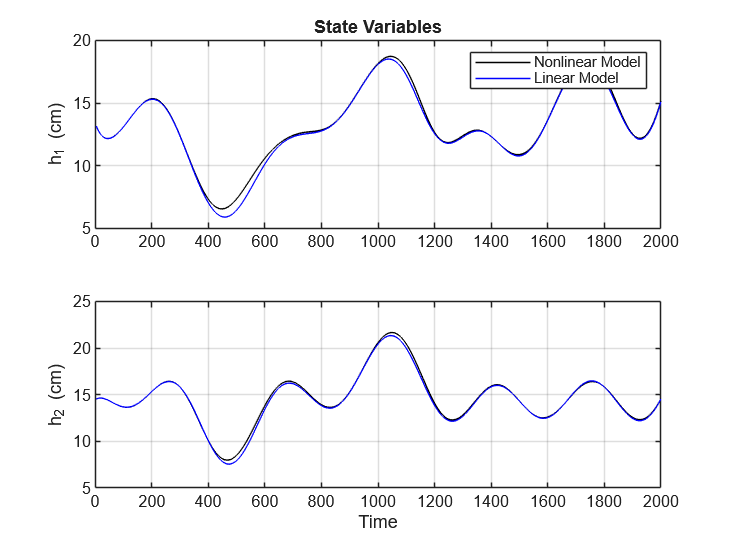

figure(1)
subplot(211), plot( kT, Xk(1,:), 'k-', kT, Xk_lin(1,:), 'b-'), grid,  ylabel('h_1 (cm)'), title('State Variables')
legend('Nonlinear Model', 'Linear Model')
subplot(212), plot(kT, Xk(2,:), 'k-', kT, Xk_lin(2,:), 'b-'), grid, ylabel('h_2 (cm)'), xlabel('Time')

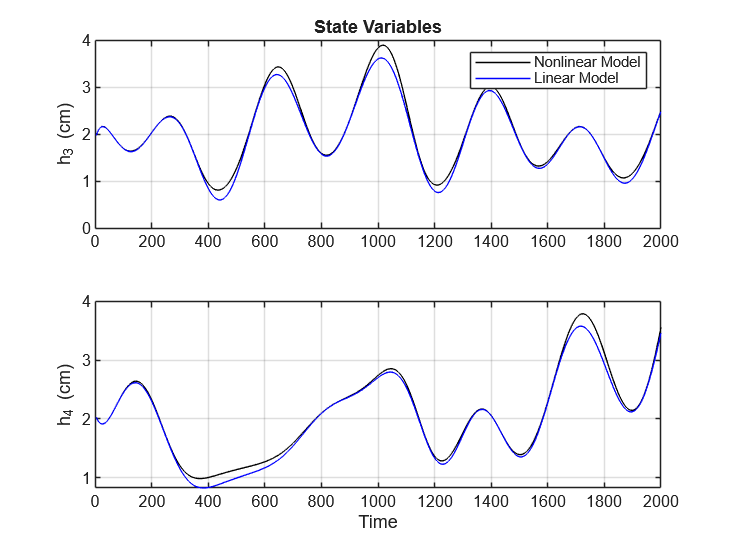

figure(2) 
subplot(211), plot(kT, Xk(3,:), 'k-', kT, Xk_lin(3,:), 'b-'), grid, ylabel('h_3 (cm)'), title('State Variables')
legend('Nonlinear Model', 'Linear Model')
subplot(212), plot(kT, Xk(4,:), 'k-', kT, Xk_lin(4,:), 'b-'), grid, ylabel('h_4 (cm)'), xlabel('Time') % ytickformat('%.2f')      

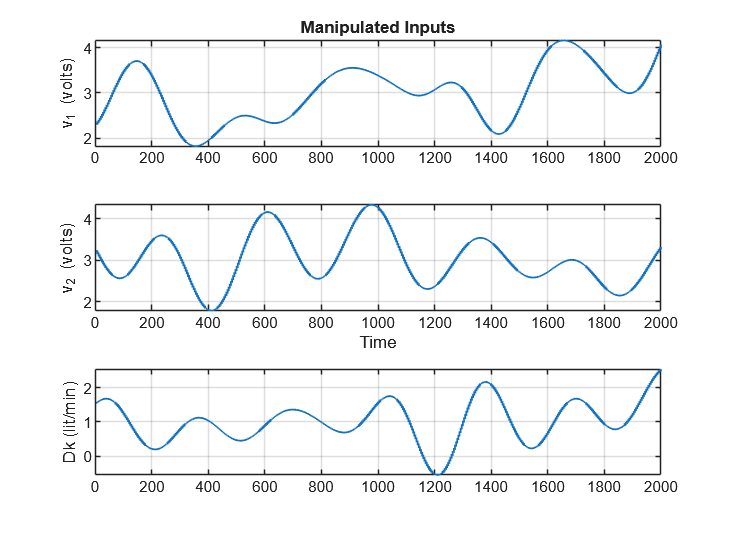

figure(3)
subplot(311), stairs(kT, Uk(1,:), '-', 'LineWidth', 1), grid, ylabel('v_1 (volts)'), title('Manipulated Inputs')
subplot(312), stairs(kT, Uk(2,:), '-', 'LineWidth', 1), grid, ylabel('v_2 (volts)'), xlabel('Time')
subplot(313), stairs(kT, Dk, '-', 'LineWidth', 1), grid, ylabel('Dk (lit/min)')

**Compare variability indices **

Let us now check the variability indices for the nonlinear and linear models (Refer equation (15)). We can observe that they are almost equal.

 disp( [ S2_index s2_index])

   1.0e+03 *

    4.4108    4.6380
    3.7719    3.8125
    0.2878    0.2737
    0.2533    0.2525



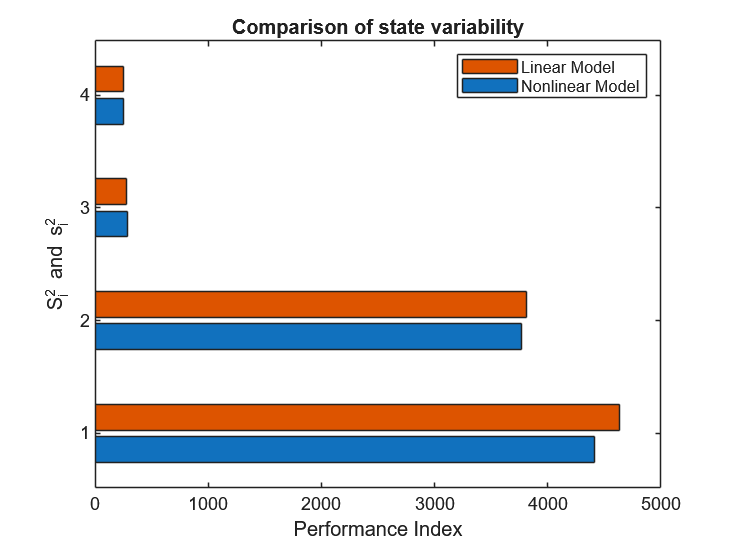

figure
barh( [ S2_index s2_index])
xlabel('Performance Index'), ylabel('S^2_i and s^2_i')
legend('Nonlinear Model','Linear Model')
title('Comparison of state variability')

**Display % approximation error**

Percentage error between two models is displayed below.

 disp(E2_index')

    0.8543    0.5795    1.7360    1.4177



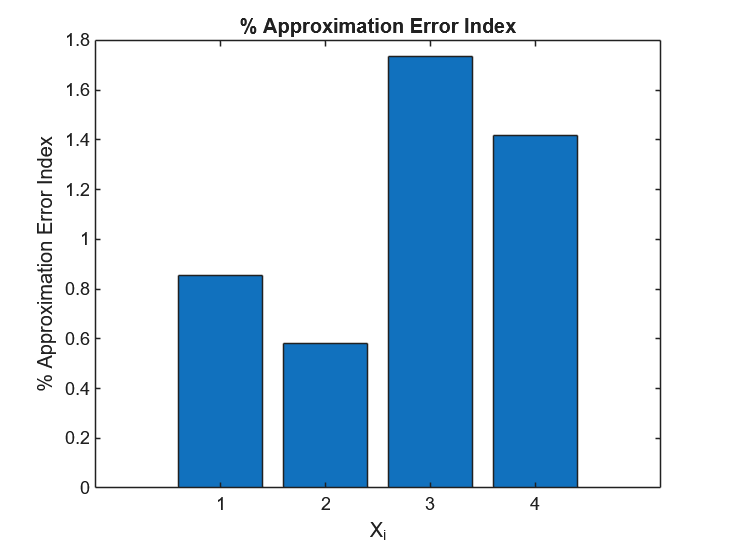

bar( E2_index)
ylabel('% Approximation Error Index'), xlabel('X_i')
title('% Approximation Error Index')

From the results of simulation, we can see that when same inputs are given to the process input variations are relatively small dynamic behavior of discrete time linear model matches the nonlinear system dynamic behavior reasonably well. This can be easily seen from the variability indicess and Approximation Error Index.

**Task 7:** Now change the operating point and again observe the results. We can observe similar results for both the operating points.

**Task 8: **Go to Task 3 and try changing the input where changes are given. 

**Task 9: **Go to Task 4 and try giving more step/ rbs/ rgs changes in inputs, now observe the effect on outputs of linear and nonlinear models. Notice the difference in the outputs. 

## Conclusion

In this lesson, we have verified the accuracy of discrete time linear model as compared with the exact nonlinear model, and can conclude that, 

- When input variations are relatively small, dynamic behavior of discrete time linear model matches the nonlinear system dynamic behavior reasonably well and % approximation errors are smaller 

- Larger mismatch develops between linear and nonlinear model based simulations for larger magnitude input perturbations. However, the linear model is able to capture qualitative behavior of state dynamics reasonably well even for large magnitude perturbations. 

In industrial processes, the linear model may not perform well or the approximation may not be very accurate if the process in highly nonlinear and the operating range is wide. However such a model is suitable for implementing a model based controller when the process exhibits mildly nonlinear behavior as in the case of Quadruple Tank system. Having obtained the linear discrete time space models for a nonlinear dynamic system, we now develop predictive controllers by employing discrete linear perturbation models for carrying out prediction. In the[ next lesson](matlab:open('./L05_Reformulation_of_MovingHorizonControl.mlx')), we will demonstrate implementation of MHOPC-2 using the linear discrete time perturbation model given by equation (14). 

## References:

[1] Astrom, K. J., and B. Wittenmark, Computer Controlled Systems, Prentice Hall India (1994).

[2] Franklin, G. F., Powell, J. D., and M. L. Workman, Digital Control Systems, Addison Wesley, 1990. 

[3] Johansson, K. H. (2000). The Quadruple-Tank Process: A multivariable laboratory process with an adjustable zero, IEEE Trans. on Control Systems Technology, 8(3), 456-465.

[4] Marlin, T. E., Process Control, McGraw Hill, 2014. 

[5] Goodwin, G. C., Graebe, S. F.  and M. E. Salgado, Control Systems Design, Prentice Hall India, 2003. 